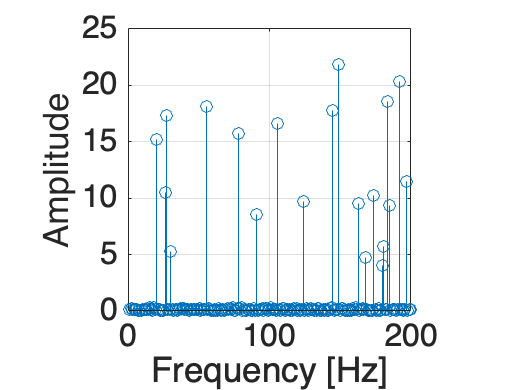

rng(0)
N = 200;
M = 100;

% --- build a sparse frequency-domain truth ALPHA ---
p = 0.10;                         % 10% sparsity
K = round(p*N);
supp = randperm(N, K);
X = 0.1*(randn(N,1) + 1j*randn(N,1));      % small background
X(supp) = 10*(randn(K,1) + 1j*randn(K,1)); % large tones

% --- unitary DFT and inverse ---
F = (1/sqrt(N)) * fft(eye(N));    % DFT (N×N)
Psi = F';                         % inverse DFT (frequency -> time)

% --- time-domain uniform signal (lowercase) ---
x = Psi * X;        % x ∈ C^N

% --- non-uniform time sampling operator Phi (M×N selection) ---
t = linspace(0,1,M);
g = t.^1.8;                       % gradual non-uniform schedule
idx = round(1 + g*(N-1));
idx = unique(idx,'stable');
while numel(idx) < M
    free = setdiff(1:N, idx);
    need = M - numel(idx);
    idx = [idx, free(round(linspace(1,numel(free),need)))];
    idx = unique(idx,'stable');
end
idx = idx(1:M);

Phi = eye(N);
Phi = Phi(idx, :);                % Phi is M×N (select rows)

% --- measurements in time-domain (lowercase y) ---
y = Phi * x;                 % y ∈ C^M
A = Phi * Psi;                    % M×N system: y = A * ALPHA

f = figure;
stem(abs(X))
xlabel('Frequency [Hz]', 'FontSize', 16)
ylabel('Amplitude', 'FontSize', 16)
axis square
grid on
ax = gca;
set(ax,'FontSize',16)

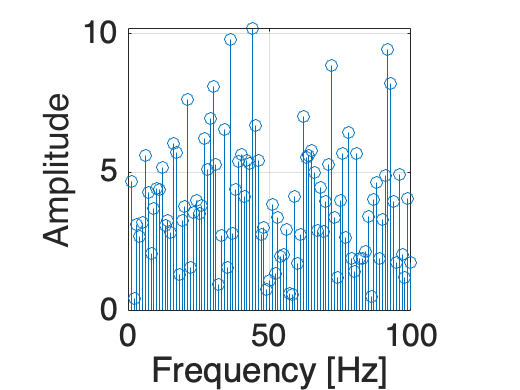

%saveas(f,'plots/X.png')

FM = (1/sqrt(M)) * fft(eye(M));    % DFT (N×N)

f = figure;
stem(abs(fftshift(FM * y)))
xlabel('Frequency [Hz]', 'FontSize', 16)
ylabel('Amplitude', 'FontSize', 16)
axis square
grid on
ax = gca;
set(ax,'FontSize',16)

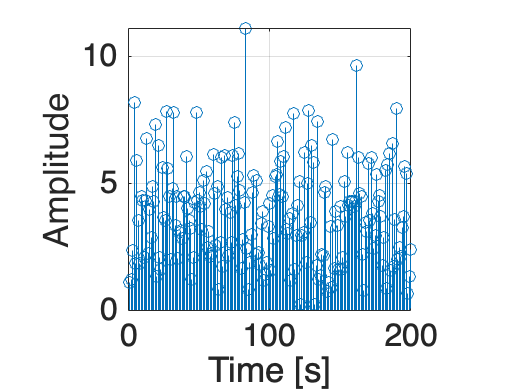

%saveas(f,'plots/Y.png')

f = figure;
stem(abs(x))
xlabel('Time [s]', 'FontSize', 16)
ylabel('Amplitude', 'FontSize', 16)
axis square
grid on
ax = gca;
set(ax,'FontSize',16)
saveas(f,'plots/x.png')

f = figure;
stem(abs(y))
xlabel('Time [s]', 'FontSize', 16)
ylabel('Amplitude', 'FontSize', 16)
axis square
grid on
ax = gca;
set(ax,'FontSize',16)
saveas(f,'plots/y.png')

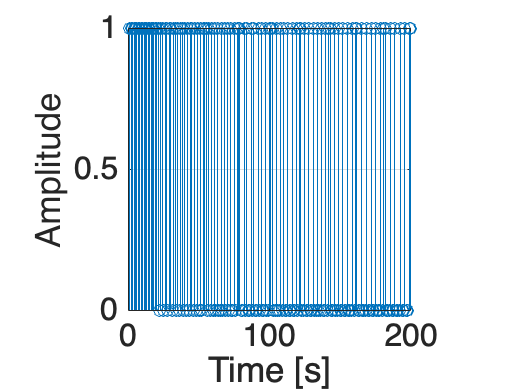

sampling = zeros(N,1);
sampling(idx) = true;
f = figure;
stem(sampling)
xlabel('Time [s]', 'FontSize', 16)
ylabel('Amplitude', 'FontSize', 16)
axis square
grid on
ax = gca;
set(ax,'FontSize',16)

% saveas(f,'plots/x.png')

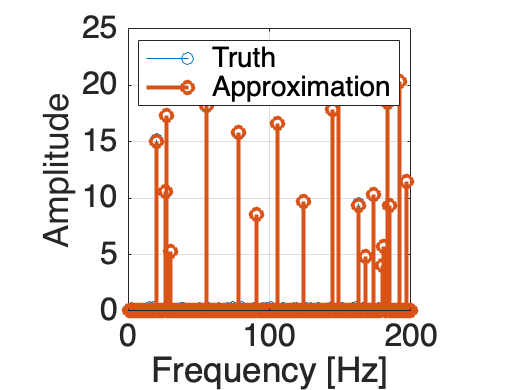

% optional noise
sigma = 0.0;
y = y + sigma*(randn(M,1) + 1j*randn(M,1));

% --- OMP to recover ALPHA ---
% normalize columns to improve selection
cn = vecnorm(A);
A_n = A ./ cn;

% Apply compressive sensing techniques using the orthogonal
% matching pursuit method which assumes the columns of A
% (iid Gaussian) are roughly orthogonal. The goal is to
% determine the basis vector in A that is overlaps the most
% with the measurement. This overlap is determined by an
% inner product between the measurement and each vector,
% resulting in the transformation coefficients. The greater
% the magnitude of the coefficient, the greater the overlap.
% Select the basis vector in A with the greatest inner
% product, and solve for an approximation of signal by
% minimizing || y - Ax ||_{2}^{2} using the least squares method 

% initialize the array containing the approximate non-zero
% indices
Lambda = []; X_hat = zeros(N,1);

% for now, assume we have knowledge of the number of
% nonzeros
r = y;
for i = 1:K

    % inner product of the measurement and basis vectors
    c = A'* r;

    % find the index that maximizes the inner product
    [~, l] = max(abs(c));
    Lambda = [Lambda; l];

    % use this basis vector to calculate the least squares
    % solution
    X_hat(Lambda) = inv(A(:,Lambda)'*A(:,Lambda))*A(:,Lambda)'*y;
    r = y - A * X_hat;
end

x_hat = Psi * X_hat;

f = figure;
stem(1:size(X,1),abs(X), 'DisplayName', 'Truth')
hold on
stem(1:size(X_hat,1),abs(X_hat),'DisplayName','Approximation', 'LineWidth',2)
%title('Truth signal v CS approximation','FontSize',24)
xlabel('Frequency [Hz]','FontSize',16)
ylabel('Amplitude','FontSize',16)
legend
axis square
grid on
ax = gca;
set(ax,'FontSize',16)
saveas(f,'plots/recon_fft.png')

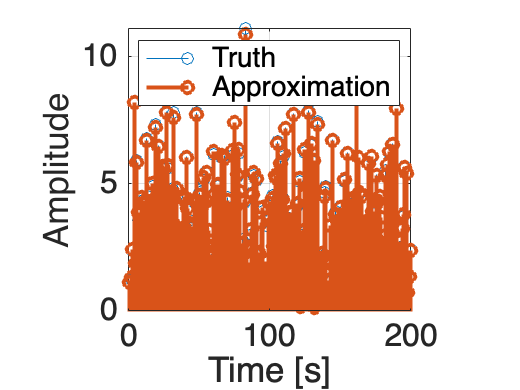


f = figure;
stem(1:size(x,1),abs(x), 'DisplayName', 'Truth')
hold on
stem(1:size(x_hat,1),abs(x_hat),'DisplayName','Approximation','LineWidth',2)
%title('Truth signal v CS approximation','FontSize',24)
xlabel('Time [s]','FontSize',16)
ylabel('Amplitude','FontSize',16)
legend
axis square
grid on
ax = gca;
set(ax,'FontSize',16)
saveas(f,'plots/recon_t.png')